## Growth

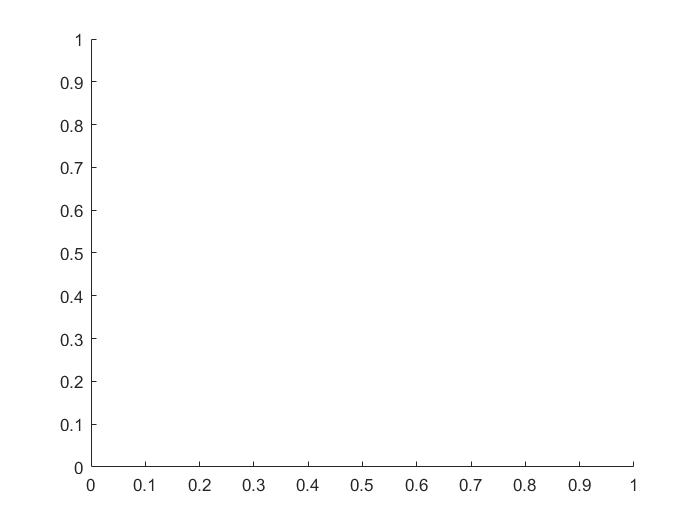

c0 = solubility(60+273.15);
cfl = 0.1;
tspan = 1*300;
T = 273.15+25;
c_theoretical = solubility(T);
lstep = 1;
k_s = 0.48;
density_ratio = 1.54;
xrange = 0:lstep:999;
crossing_threshold = 1e-5;
x0 = normpdf(xrange, 40, 30) * 0; 
seed = particle_moment(lstep, x0, 3) / 1e18 * density_ratio; % kg/kg
[xs, cs, ts] = hrfvm_solver(x0', c0, cfl, tspan, T, lstep, k_s, density_ratio, crossing_threshold);


figure;
hold on;

stem(ts, cs);
plot([ts(1); ts(end)], [c_theoretical, c_theoretical], 'r--')

Index exceeds the number of array elements (0).



figure;
[ll, tt] = meshgrid(xrange, ts);
surf(tt, ll, xs);


figure;
plot(xrange, xs(1:5:end, :));

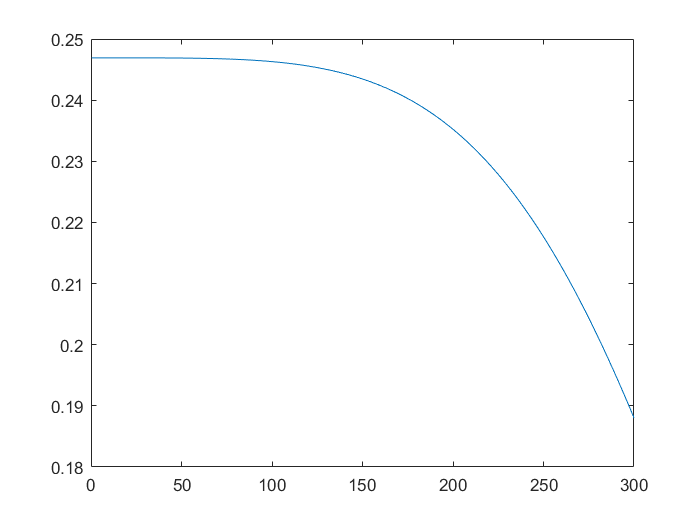

figure;
plot(ts, GDs);

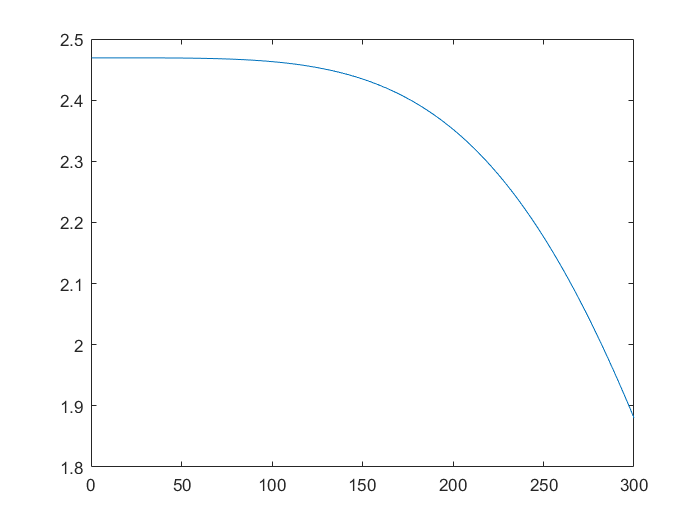


figure;
plot(ts, sigmas);

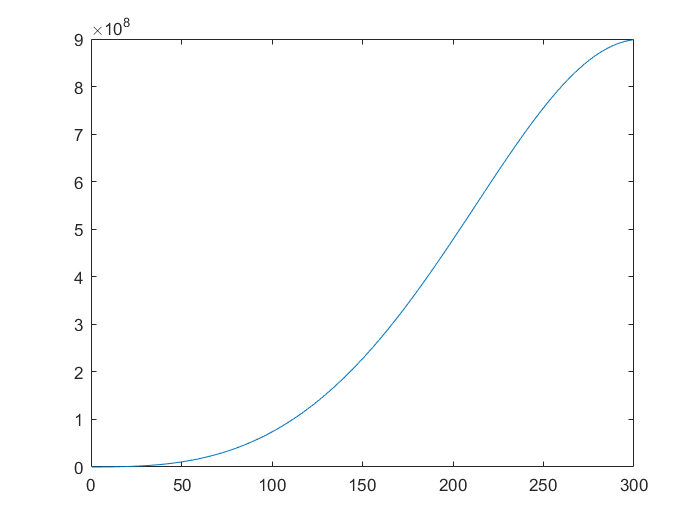


figure;
plot(ts, Bss);

## Dissolution

c0 = solubility(10+273.15);
cfl = 0.1;
tspan = 500;
T = 273.15+25;
c_theoretical = solubility(T);
lstep = 1;
k_s = 0.48

k_s = 0.4800

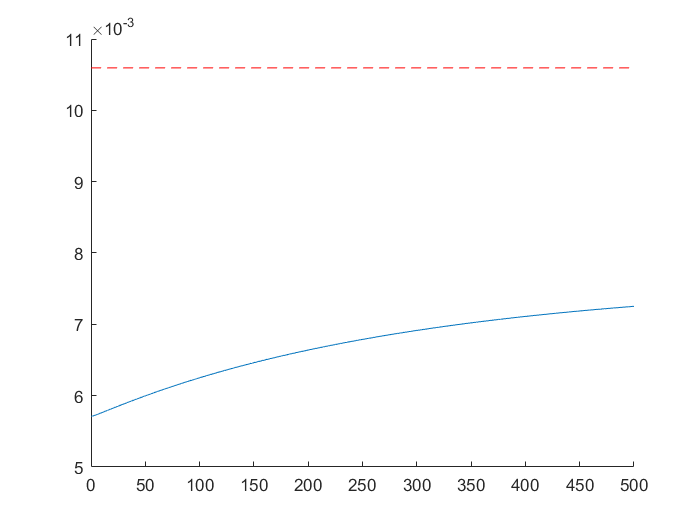

density_ratio = 1.54;
xrange = 0:999;

x0 = ones(size(xrange)) * 1e4; 
seed = particle_moment(lstep, x0, 3) / 1e18 * density_ratio; % kg/kg
[xs, cs, ts] = hrfvm_solver(x0', c0, cfl, tspan, T, lstep, k_s, density_ratio, crossing_threshold);


figure;
hold on;
plot(ts, cs);
plot([ts(1); ts(end)], [c_theoretical, c_theoretical], 'r--')



% figure;
% [ll, tt] = meshgrid(xrange, ts);
% surf(tt, ll, xs);
% 
% 
% figure;
% plot(xrange, xs(1:5:end, :));